testImageIdx = 1

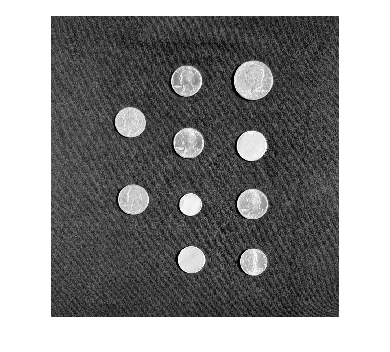

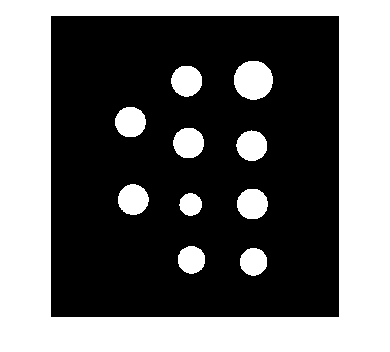

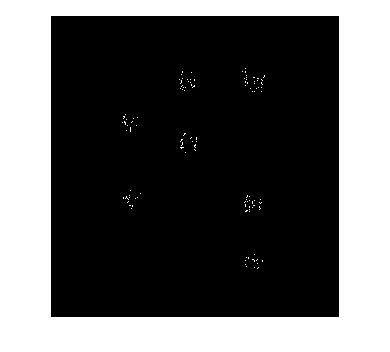

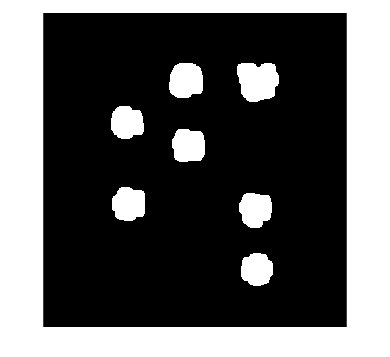

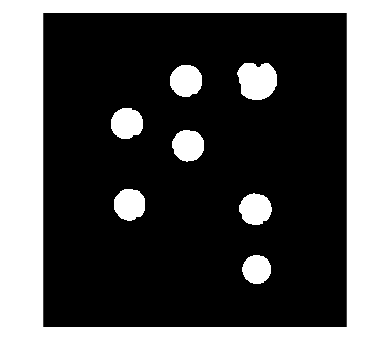

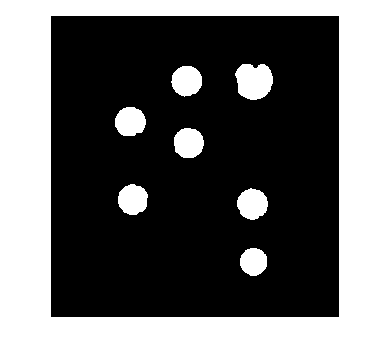

testImageIdx = randi([1,3])
testCoinImage = imread("testCoinImage"+testImageIdx+".png");
%call segmentation function
[testCoinMask,maskedTestCoin]= segmentImageCoinTest(testCoinImage);
% Shrink the coin mask.
se = strel('disk', 15, 6);
testCoinMask2 = testCoinMask;
imshow(testCoinMask2)
testCoinMask = imfill(testCoinMask, 'holes'); % Fill any holes in it.
testCoinMask = imerode(testCoinMask, se); % Shrink by 3 layers of pixels.

imgFilt = imgaussfilt(maskedTestCoin,0.5,Padding="circular",FilterDomain="frequency",FilterSize=1);
faceEdgeMask= edge(imgFilt,"sobel",0.075,"both");
faceEdgeMask(~testCoinMask) = false;
imshow(faceEdgeMask)
%Passed

faceEdgeMask = imresize(faceEdgeMask, [600 580]);

faceEdgeMaskDilate = imdilate(faceEdgeMask,se);
imshow(faceEdgeMaskDilate)
testCoinMask2 = imresize(testCoinMask2, [600 580]);
validCoinMask = faceEdgeMaskDilate & testCoinMask2;
imshow(validCoinMask)
validCoinMask(~testCoinMask2) = 0;
validCoinMask = imresize(validCoinMask, [972 930]);
imshow(validCoinMask)